clear, clc

filename_root = "data\";
data_dirs = ["Case-1-2.06-0.7001" "Case-2-2.05-0.9180" "Case-3-6.07-0.9298"];
data_paths = filename_root + data_dirs + "\";


LegendLabels = ["Experimental" "Fluent, k-\omega SST"];

SectionLocations = ["0.20" "0.44" "0.65" "0.80" "0.90" "0.96" "0.99"];
NumSections = length(SectionLocations);
Angles = ["2.06" "2.05" "6.07"];
MachNumbers = ["0.7001" "0.9180" "0.9298"];

filenamestring = "cp-comparison-1-0.20.png"

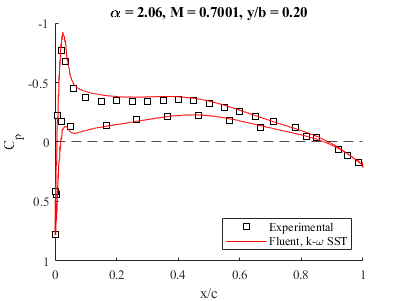

filenamestring = "cp-comparison-1-0.44.png"

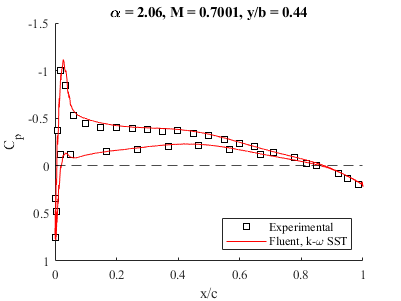

filenamestring = "cp-comparison-1-0.65.png"

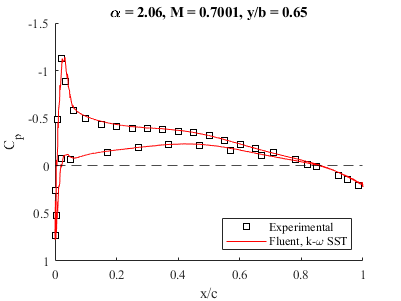

filenamestring = "cp-comparison-1-0.80.png"

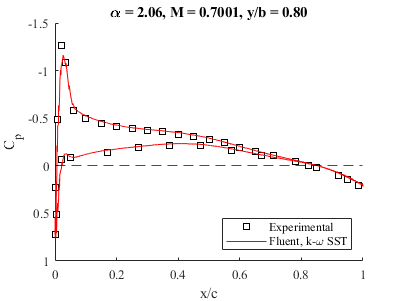

filenamestring = "cp-comparison-1-0.90.png"

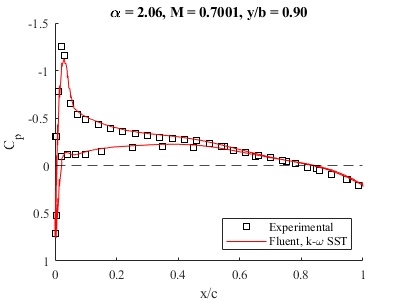

filenamestring = "cp-comparison-1-0.96.png"

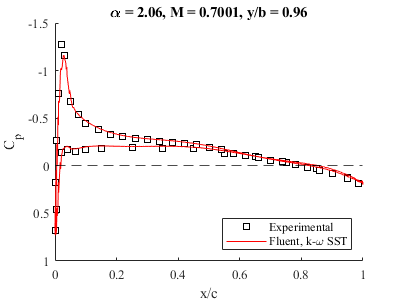

filenamestring = "cp-comparison-1-0.99.png"

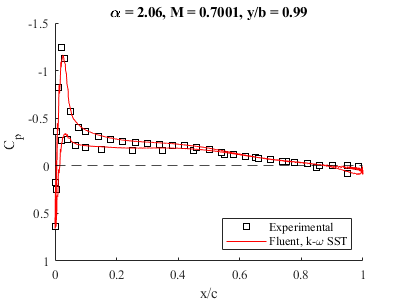

filenamestring = "cp-comparison-2-0.20.png"

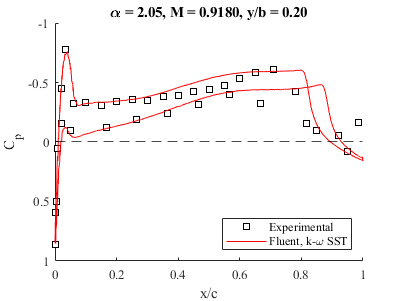

filenamestring = "cp-comparison-2-0.44.png"

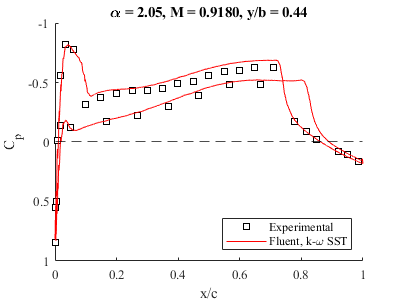

filenamestring = "cp-comparison-2-0.65.png"

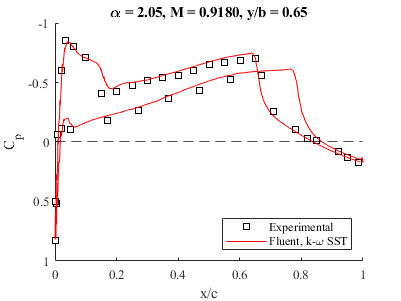

filenamestring = "cp-comparison-2-0.80.png"

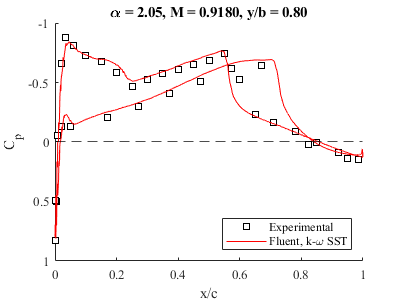

filenamestring = "cp-comparison-2-0.90.png"

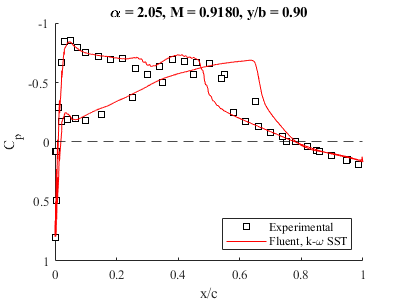

filenamestring = "cp-comparison-2-0.96.png"

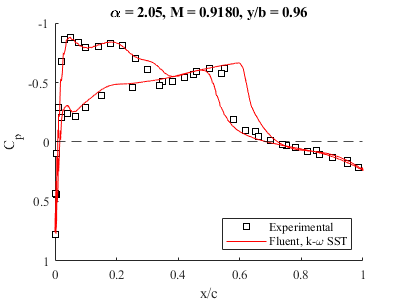

filenamestring = "cp-comparison-2-0.99.png"

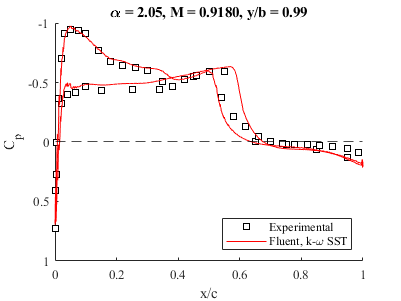

filenamestring = "cp-comparison-3-0.20.png"

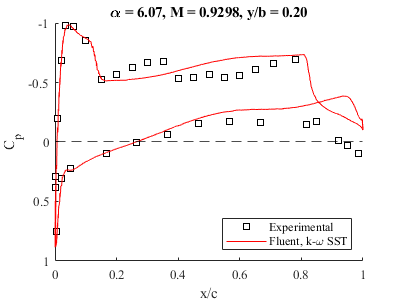

filenamestring = "cp-comparison-3-0.44.png"

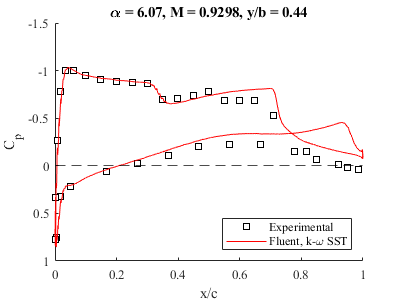

filenamestring = "cp-comparison-3-0.65.png"

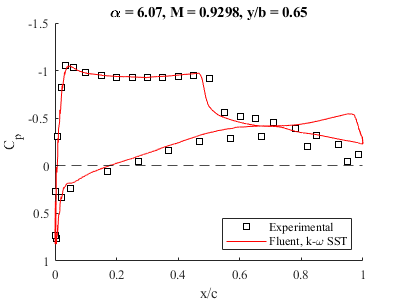

filenamestring = "cp-comparison-3-0.80.png"

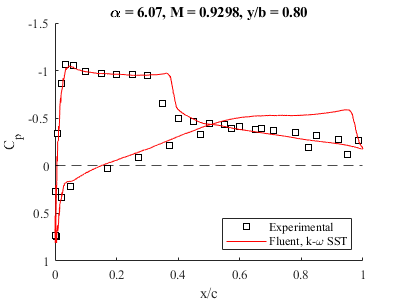

filenamestring = "cp-comparison-3-0.90.png"

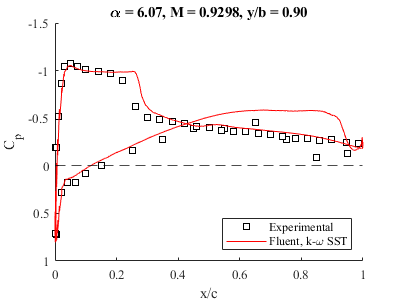

filenamestring = "cp-comparison-3-0.96.png"

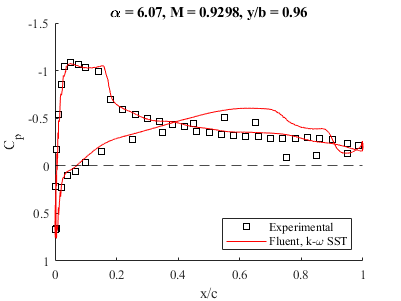

filenamestring = "cp-comparison-3-0.99.png"

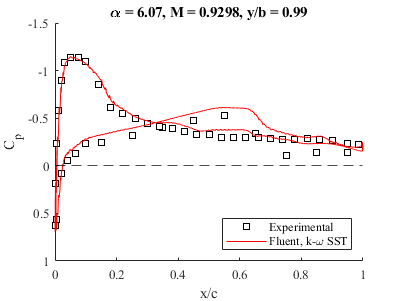

for DataFileIndex = [1 2 3]
for SectionIndex = 1:NumSections

    load(data_paths(DataFileIndex)+"FluentCpData.mat")
    load(data_paths(DataFileIndex)+"ExpCpData.mat")

    Graph = figure;
    CpLines = gobjects(1,3);

    ax = axes;
    ax.XLabel.String = 'x/c';
    ax.YLabel.String = 'C_p';
    ax.YDir = 'reverse';
    ax.FontName = 'Times';

    CpLines(1) = line(ExpCpData{SectionIndex}(:,1),ExpCpData{SectionIndex}(:,2));
    CpLines(2) = line(FluentCpDataUpper{SectionIndex}(:,1),FluentCpDataUpper{SectionIndex}(:,2));
    CpLines(3) = line(FluentCpDataLower{SectionIndex}(:,1),FluentCpDataLower{SectionIndex}(:,2));
    CpLines(4) = yline(0);

    for iter = 1
    CpLines(iter).Color = 'k';
    CpLines(iter).LineStyle = 'none';
    CpLines(iter).MarkerFaceColor = 'w';
    CpLines(iter).MarkerEdgeColor = 'k';
    CpLines(iter).Marker = 's';
    end

    for iter=2:3
    CpLines(iter).Color = 'r';
    end

    CpLines(4).LineStyle = '--';
    CpLines(4).LineWidth = 0.5;
    CpLines(4).Color = 'k';

    title("\alpha = " + Angles(DataFileIndex) + ", M = " + MachNumbers(DataFileIndex) + ", y/b = " + SectionLocations(SectionIndex));

    lgd = legend;
    lgd.String = LegendLabels;
    lgd.FontName = 'Times';
    lgd.Location = 'southeast';
    
    filenamestring = "cp-comparison-" + num2str(DataFileIndex) + "-" + SectionLocations(SectionIndex) + ".png"
    exportgraphics(gcf,"graphs\"+filenamestring,"Resolution",300)
end
end